# DeGroot classico 

Simulazione del modello Degroot classico su rete toy su $n=6$ agenti

clear; clc; close all;

## 1. Definizione della rete

La rete è definita attraverso dei nodi collegati da archi orientati con peso $a_{\mathrm{ij}}$. 

Gli elementi $a_{\mathrm{ij}}$ della adjacency matrix vengono usati per definire la matrice di influenza $W$. 

n = 6;

weight_case = "Case C";

switch weight_case
    case "Case A"
        W = zeros(n);

        W(1,2) = 0.4; W(1,1) = 0.6;
        W(2,1) = 0.3; W(2,3) = 0.3; W(2,2) = 0.4;
        W(3,2) = 0.2; W(3,4) = 0.2; W(3,6) = 0.2; W(3,3) = 0.4;
        W(4,3) = 0.2; W(4,5) = 0.2; W(4,6) = 0.2; W(4,4) = 0.4;
        W(5,4) = 0.4; W(5,5) = 0.6;
        W(6,3) = 0.3; W(6,4) = 0.3; W(6,6) = 0.4;
        case_name = "Case A";

    case "Case B"
        W = zeros(n);

        W(1,2) = 0.6; W(1,1) = 0.4;
        W(2,1) = 0.2; W(2,3) = 0.5; W(2,2) = 0.3;
        W(3,2) = 0.15; W(3,4) = 0.35; W(3,6) = 0.2; W(3,3) = 0.3;
        W(4,3) = 0.25; W(4,5) = 0.25; W(4,6) = 0.2; W(4,4) = 0.3;
        W(5,4) = 0.5; W(5,5) = 0.5;
        W(6,3) = 0.4; W(6,4) = 0.3; W(6,6) = 0.3;
        case_name = "Case B";

    case "Case C"
        W = zeros(n);

        W(1,2) = 0.3; W(1,1) = 0.7;
        W(2,1) = 0.25; W(2,3) = 0.25; W(2,2) = 0.5;
        W(3,2) = 0.1; W(3,4) = 0.25; W(3,6) = 0.25; W(3,3) = 0.4;
        W(4,3) = 0.3; W(4,5) = 0.15; W(4,6) = 0.15; W(4,4) = 0.4;
        W(5,4) = 0.3; W(5,5) = 0.7;
        W(6,3) = 0.2; W(6,4) = 0.3; W(6,6) = 0.5;
        case_name = "Case C";
    otherwise
        error('case_id deve essere 1, 2 oppure 3');
end

disp("Selected case: " + case_name)

Selected case: Case C


Plot del grafo:

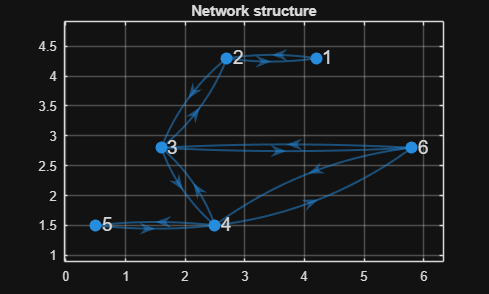

A_plot = double(W ~= 0);
A_plot(1:n+1:end) = 0;
G = digraph(A_plot.');

xpos = [4.2 2.7 1.6 2.5 0.5 5.8];
ypos = [4.3 4.3 2.8 1.5 1.5 2.8];

figure;
p = plot(G,'XData', xpos,'YData', ypos,'NodeLabel', 1:n,'NodeFontSize', 14,'MarkerSize', 8,'LineWidth', 1.5,'ArrowSize', 12);

title('Network structure');
axis equal;
grid on;

Heatmap dell'influenza:

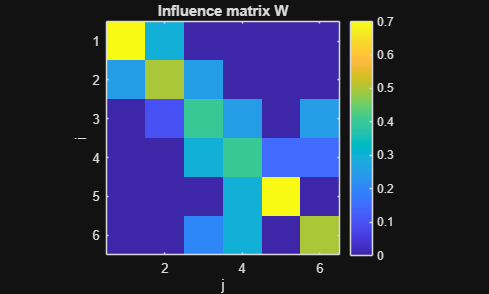

figure;
imagesc(W);
colorbar;
axis equal tight;
xlabel('j');
ylabel('i');
title('Influence matrix W');

disp(W);

    0.7000    0.3000         0         0         0         0
    0.2500    0.5000    0.2500         0         0         0
         0    0.1000    0.4000    0.2500         0    0.2500
         0         0    0.3000    0.4000    0.1500    0.1500
         0         0         0    0.3000    0.7000         0
         0         0    0.2000    0.3000         0    0.5000



imponiamo e verifichiamo la row-stochasticity: per ogni riga la somma degli elementi deve essere 1

disp('Row sums of W:');

Row sums of W:


disp(sum(W,2));

     1
     1
     1
     1
     1
     1



if any(sum(W,2)==1)
    disp('La matrice W è row-stochastic');
else
    error('La matrice W NON è row-stochastic');
end

La matrice W è row-stochastic


## 2. Definizione del modello 


$$x\left(k+1\right)=W\;x\left(k\right)$$
 

## 3. Simulazione

Condizioni iniziali $x\left(0\right)$: provo varie opzioni iniziali

%x0 = [0; 1; 0; 1; 0];
%x0 = rand(5,1); % questo randomico da sempre un output diverso
x0 = [0.1; 0.9; 0.2; 0.8; 0.3; 0.2];

numero di iterazioni dell'aggiornamento

T =25;

salvataggio delle traiettorie

X = zeros(n, T+1);
X(:,1) = x0;

aggiornamento dello stato dei nodi

for k = 1:T
    X(:,k+1) = W * X(:,k);
end

stampa delle opinioni finali di ogni agente

disp('Final opinions:');

Final opinions:


disp(X(:,end));

    0.4281
    0.4284
    0.4289
    0.4290
    0.4291
    0.4290



plot delle traiettorie 

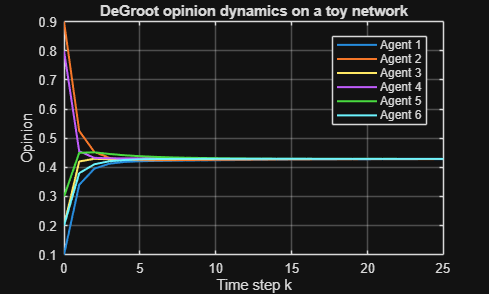

figure;
plot(0:T, X(1,:), 'LineWidth', 1.5); hold on;
plot(0:T, X(2,:), 'LineWidth', 1.5);
plot(0:T, X(3,:), 'LineWidth', 1.5);
plot(0:T, X(4,:), 'LineWidth', 1.5);
plot(0:T, X(5,:), 'LineWidth', 1.5);
plot(0:T, X(6,:), 'LineWidth', 1.5);

xlabel('Time step k');
ylabel('Opinion');
title('DeGroot opinion dynamics on a toy network');
legend('Agent 1','Agent 2','Agent 3','Agent 4','Agent 5','Agent 6','Location','best');
grid on;

stima del valore di consenso

consensus_estimate = X(:,end);
disp('Approximate consensus value:');

Approximate consensus value:


disp(mean(consensus_estimate));

    0.4288



A = double(W > 0);
G = digraph(A');

## 4. Interpretazione

Se la rete è connessa e la matrice è row-stochastic le opinioni convergono a un valore comune e il disagreement tende a zero.